# Deep Learning In 6 Lines of Code

## Load Pre-trained CNN

Pre-trained CNNs are deep networks that are already trained on thousands of different images. They can work for classification "right out of the box." 

There are several networks available from our [Add-Ons](https://www.mathworks.com/add-ons/ALEXNET/) section under the home tab. We will use a pretrained model called [AlexNet](https://en.wikipedia.org/wiki/AlexNet), which is trained on a subsection of the [ImageNet](http://www.image-net.org/) database. It classifies images of 1000 different categories. 

% Load the AlexNet neural network
[net, classNames] = imagePretrainedNetwork("alexnet");

% View the network layers and connections
% analyzeNetwork(net)

## Classify Image of "Peppers"

% Load in an image: 'peppers.png'. 
im = imread('peppers.png');

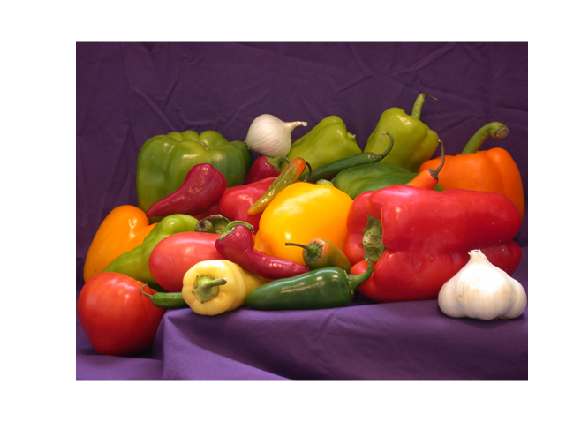


% Show the figure on the screen.
imshow(im);


% Resize the image for AlexNet requirements [227 227]
imResized = imresize(im,[227 227]);

% Classify what the image is based on the AlexNet pretrained network
X = single(imResized); % Convert to single datatype for prediction
score = predict(net,X);
Label = scores2label(score, classNames)

Label = categorical
     bell pepper 


max(score)

ans = single
0.8330

As we can see from the result, the network identified the above image as bell peppers.

*Copyright 2024 The MathWorks, Inc.*